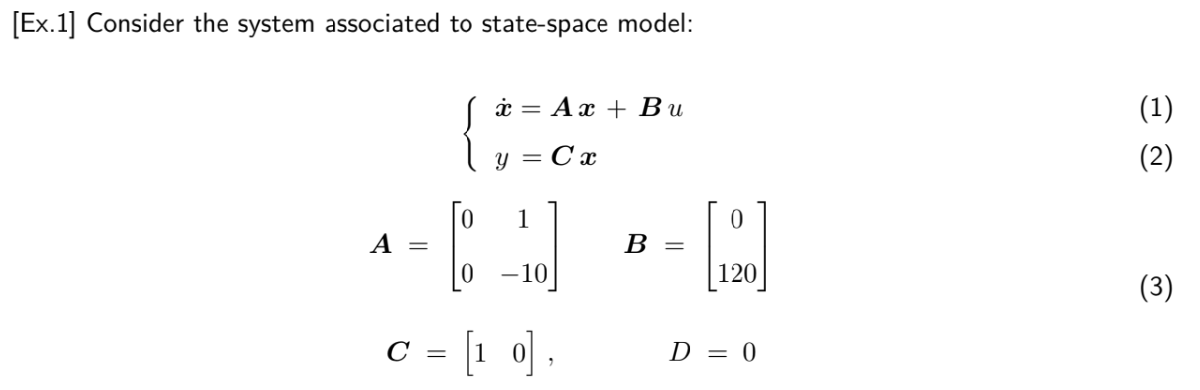

%%Implementazione sistema

clear all;
close all;
clc;

A = [0 1; 0 -10];
B = [0; 120];
C = [1 0];
D = 0;

ss_P = ss(A,B,C,D);  % associa le matrici A,B,C,D alle variabili dello state space model
poles = pole(ss_P);  % Restituisce un vettore con la posizione dei poli in s
n_poles_zero = sum(abs(poles) < 1e-6); %Calcola il numero di poli nell'origine (La toll. è necessaria a causa dei calcoli appr. di Matlab)

%%Controllore

required_integrators = 2; %Tracking rampa senza errore
controller_integrators = required_integrators - n_poles_zero; %Poli richiesti al controllore

BODE METHOD:

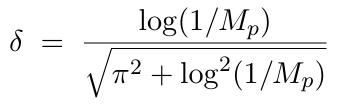

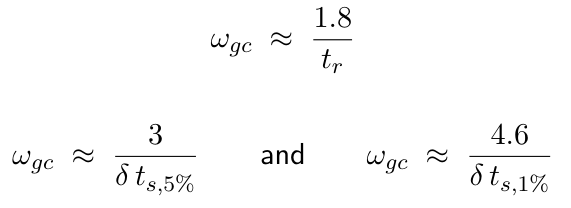

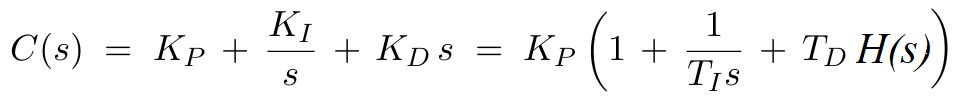

wgc is the angular frequency at which the magnitude of the open-loop chain L(jw)=C(jw)*G(jw) is equal to 1 (0 in dB)

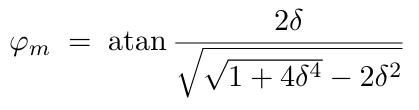

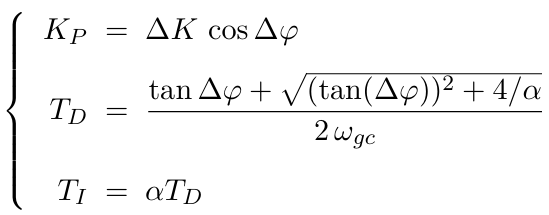

Tr = 0.15; %t rise in secondi
Mp = 0.2; %Sovraelongazione

omega_n = 1.8/Tr;
Tl = 1/(4 * omega_n);

[Mag_P_omega_n, Phase_P_omega_n_deg]= bode(ss_P,omega_n);
Phase_P_omega_n_rad = Phase_P_omega_n_deg*pi/180;

Delta_K = 1/Mag_P_omega_n;
delta = (log(1/Mp))/(sqrt(pi^2+(log(1/Mp))^2));
phi_m_rad = atan((2*delta)/(sqrt(sqrt(1+4*delta^4)-2*delta^2))); %Margine di fase desiderato
Delta_phi_rad = -pi + phi_m_rad - Phase_P_omega_n_rad;  %Quanta fase manca al processo per raggiungere il margine di fase desiderato

Kp = Delta_K*cos(Delta_phi_rad);
alpha = 100;
T_D = (tan(Delta_phi_rad)+sqrt((tan(Delta_phi_rad))^2+(4/alpha)))/(2*omega_n);
T_I = alpha * T_D;

s = tf('s');

H = s/(1+Tl*s); %Derivativo reale
Contr = Kp*(1+(1/(T_I*s))+T_D*H);


Contr =
 
  0.09473 s^2 + 2.573 s + 1.546
  -----------------------------
      0.03426 s^2 + 1.644 s
 
Continuous-time transfer function.
Model Properties


P = tf(ss_P);  % tf del processo


P =
 
     120
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


L = Contr * P;
T = feedback(L, 1);
info_step = stepinfo(T)

info_step = struct with fields:
         RiseTime: 0.0996
    TransientTime: 0.9100
     SettlingTime: 0.9100
      SettlingMin: 0.9335
      SettlingMax: 1.2429
        Overshoot: 24.2885
       Undershoot: 0
             Peak: 1.2429
         PeakTime: 0.2375
